# M6 Reciever

## Initialize parameters

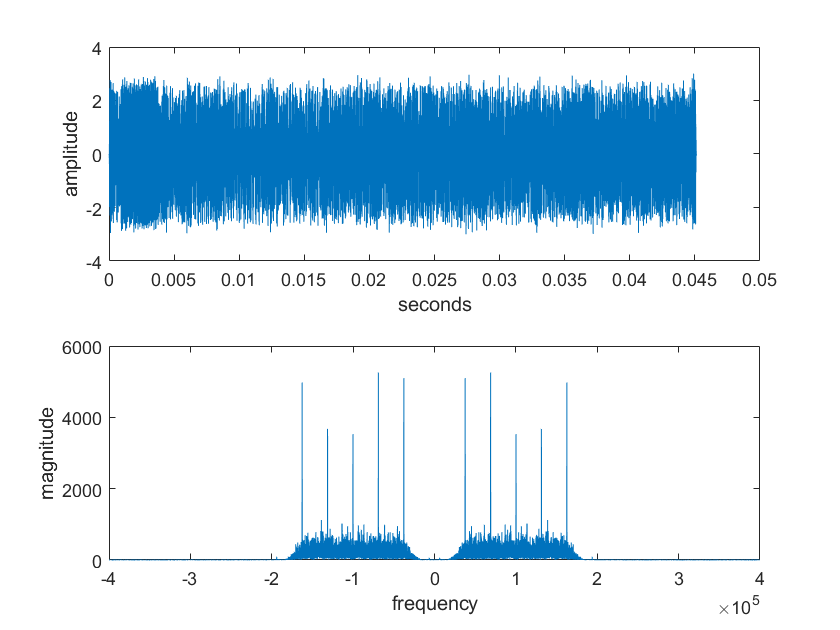

cs=input('select a signal: enter 1, 2, or 3 = ');    % Select received Signal
%% Load Receieved Signal
if cs==1
  load('mysteryA.mat');
  SRRCLength = 4;                         % Square Root Raised Cosine Length
  SRRCrolloff = 0.3;                      % Square Root Raised Cosing Rolloff factor (beta)
  fs = 800e3;                             % Sampling Frequency
  Tt = 8e-6;                              % Symbol Period
  fif = 1.7e6;                            % Intermediate Frequency
elseif cs==2
  load('mysteryB.mat');
  SRRCLength = 2;
  SRRCrolloff = 0.9;
  fs = 700e3;
  Tt = 10.2e-6;
  fif = 1.95e6;
elseif cs ==3
  load('mysteryC.mat');
  SRRCLength = 3;                         % Square Root Raised Cosine Length
  SRRCrolloff = 0.5;                      % Square Root Raised Cosing Rolloff factor (beta)
  fs = 750e3;                             % Sampling Frequency
  Tt = 8.3e-6;                            % Symbol Period
  fif = 2.45e6;                           % Intermediate Frequency
end

if (fif < fs)
fc = fif;   
elseif (fif > fs)
  k = round(fif/fs);  
  fc = abs(fif - k*fs);                             % carrier frequency
end

M = fs*Tt;                                           % upsampling ratio
fq = fs/2;                                           % Nyquest frequency

r = r';                                              % Transpose received signal


figure(1), plotspec(r, 1/fs);

## Carrier Recovery

## Dual Costas Loop

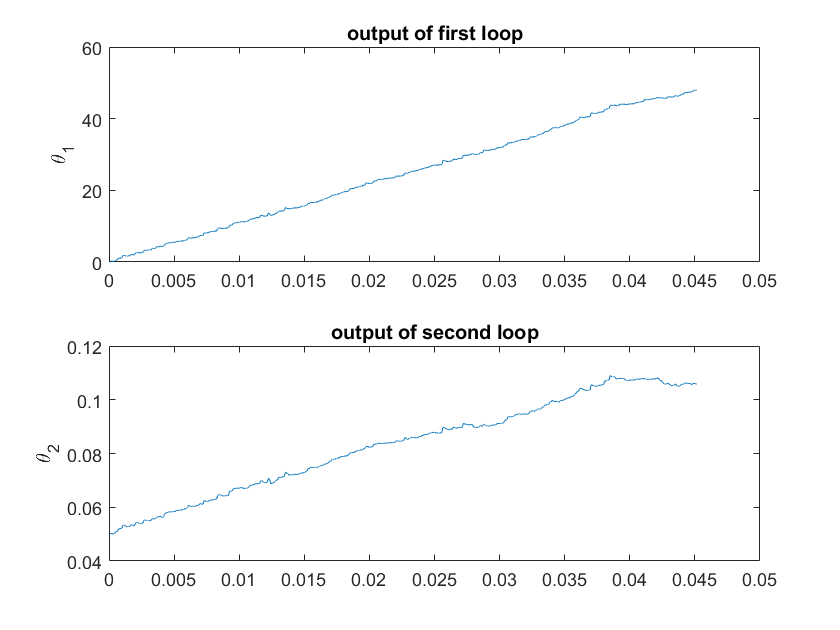

t = 0:(1/fs):((length(r)/fs)-(1/fs));                  % Initialize Time Vector
f0=fc;                                    % assumed freq. at receiver

%% The code is based on costasloop.m and dualpll.m from SDR package.
% Initialize LPF For the loops
fl=100; ff=[0 .01 .02 1]; fa=[1 1 0 0];
h=firpm(fl,ff,fa);                        % LPF design

% First Loop Parameters
mu1=.04;                                  % algorithm stepsize
theta1=zeros(1,length(r)); theta1(1)=0;   % initialize estimate vector
zs=zeros(1,fl+1); zc=zeros(1,fl+1);       % initialize buffers for LPFs

% Second Loop Parameters
mu2=.00009;                                 % algorithm stepsize
theta2=zeros(1,length(r)); theta2(1)=0.05;   % initialize estimate vector 2
zs2=zeros(1,fl+1); zc2=zeros(1,fl+1);     % initialize buffers 2 for LPFs

% Initialize carrier estimate vector
carest=zeros(1,length(r));

% Run Costas Algorithm
for k=1:length(r)-1                       % z's contain past fl+1 inputs
  % First Loop
  zs=[zs(2:fl+1), 2*r(k)*sin(2*pi*f0*t(k)+theta1(k))];
  zc=[zc(2:fl+1), 2*r(k)*cos(2*pi*f0*t(k)+theta1(k))];
  lpfs=fliplr(h)*zs'; lpfc=fliplr(h)*zc'; % new output of filters
  theta1(k+1)=theta1(k)-mu1*lpfs*lpfc;    % algorithm update
  
  % Second Loop
  zs2=[zs2(2:fl+1), 2*r(k)*sin(2*pi*f0*t(k)+theta1(k) + theta2(k))];
  zc2=[zc2(2:fl+1), 2*r(k)*cos(2*pi*f0*t(k)+theta1(k) + theta2(k))];
  lpfs2=fliplr(h)*zs2'; lpfc2=fliplr(h)*zc2'; % new output of filters
  theta2(k+1)=theta2(k)-mu2*lpfs2*lpfc2;      % algorithm update 
  
  % Carrier Estimation update
  carest(k)=cos(2*pi*f0*t(k)+theta1(k)+theta2(k));
end
figure(6),
subplot(2,1,1), plot(t,theta1)              % plot first theta
title('output of first loop')
ylabel('\theta_1')
subplot(2,1,2), plot(t,theta2)              % plot second theta
title('output of second loop')
ylabel('\theta_2')

## Downconversion

## Mixer

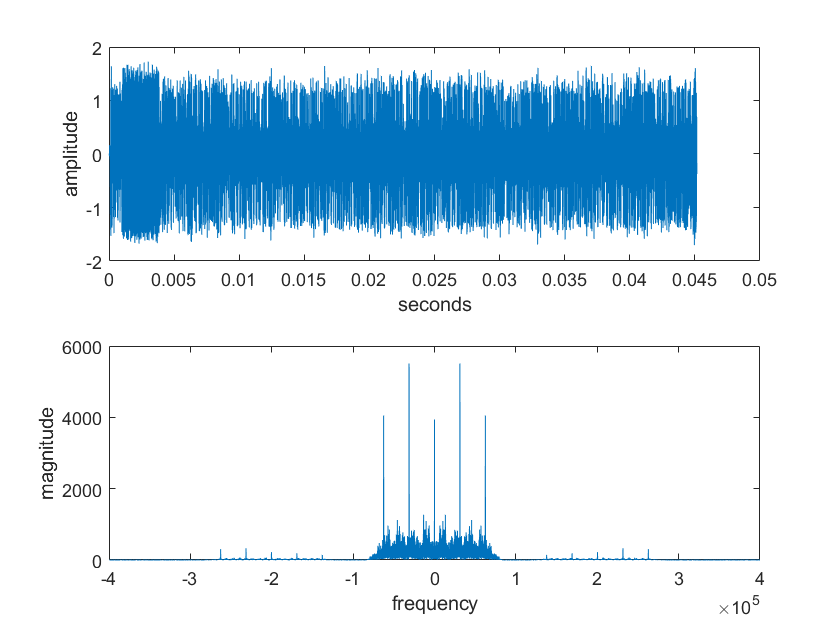

x = r.*carest;
figure(7), plotspec(x, 1/fs);
freqs=[0 0.2 0.21 1];
amps=[1 1 0 0];
b=firpm(100,freqs,amps);                % specify the LP filter
x2=filter(b,1,x);                      % do the filtering
figure(8),plotspec(x2,1/fs);              % plot the output spectrum

## Matching Filter

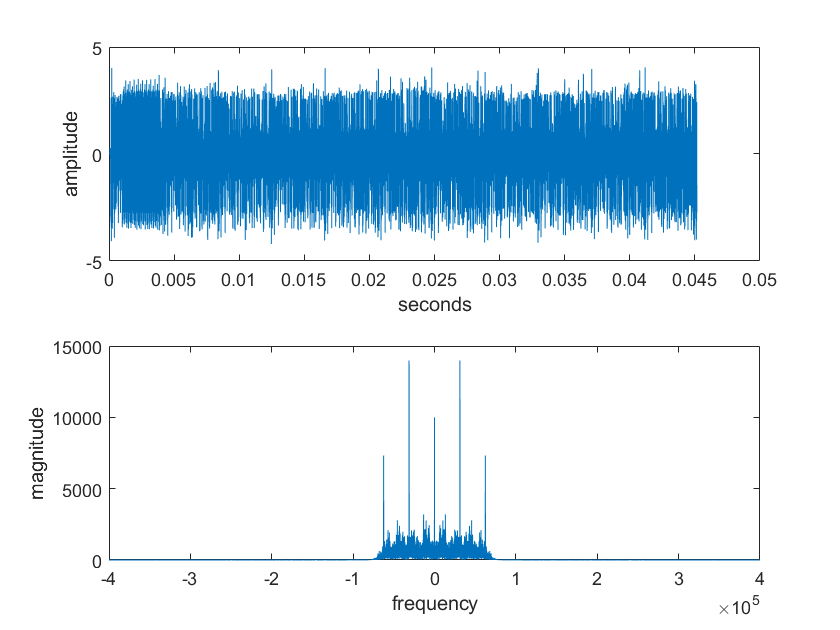

%% The Code is based on matchfilt.m of SDR package

% extract upsampled pulses using correlation implemented as a convolving filter
%v=filter(srrc(SRRCLength,SRRCrolloff,M),1,x2);  % matched filter with data
recfilt=srrc(SRRCLength,SRRCrolloff,M);                     % receive filter H sub R
%%recfilt=recfilt/sqrt(sum(recfilt.^2));   % normalize the pulse shape
v=filter(fliplr(recfilt),1,x2);           % matched filter with data
figure(9), plotspec(v, 1/fs);

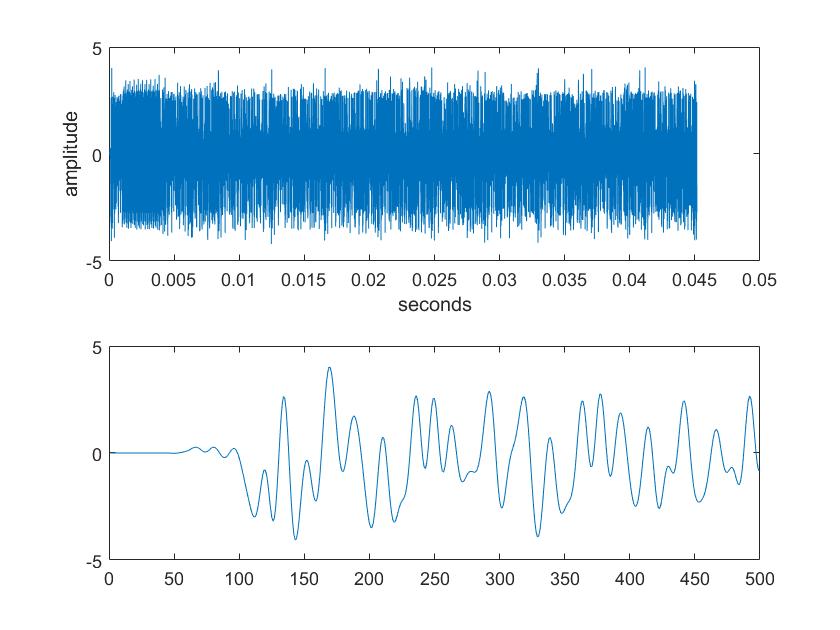


figure(10), plot(v(1:500));

## Time Recovery

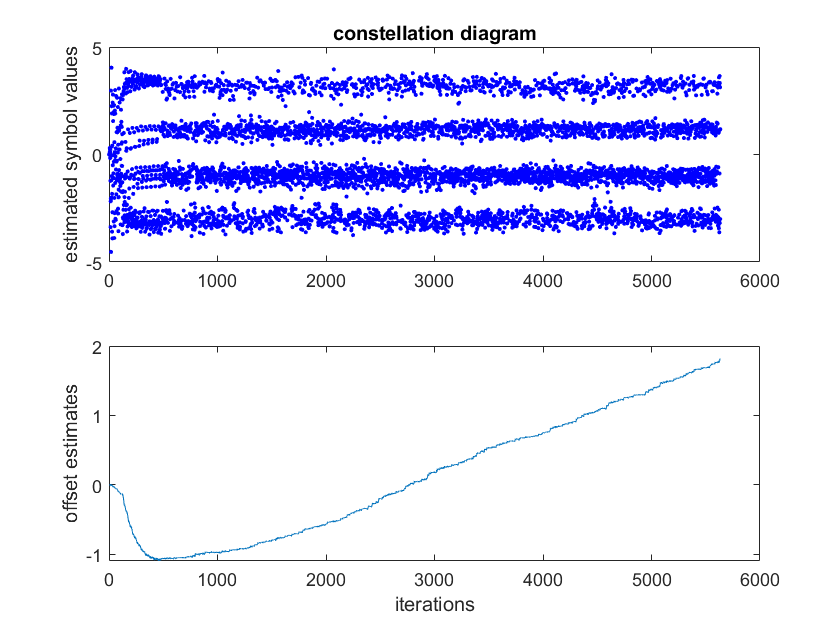

%%Based on clockrecOP.m

% run clock recovery algorithm
m = M;
n = round(length(v)/m);
l = SRRCLength;
b = SRRCrolloff;

tnow=l*m+1; tau=0; tau2=0; xs=zeros(1,n);           % initialize variables
xs2=zeros(1,n); y=zeros(1,n); 
tausave=zeros(1,n); tausave(1)=tau; i=0;
tausave2=zeros(1,n); tausave2(1)=tau2;
mu=0.01;                                    % algorithm stepsize
mu2=0.002;                                    % algorithm stepsize
delta=0.5;                                  % time for derivative
delta2=2;                                  % time for derivative
while tnow<length(v)-l*m                    % run iteration
  i=i+1;
  xs(i)=interpsinc(v,tnow+tau,l);           % interpolated value at tnow+tau
  x_deltap=interpsinc(v,tnow+tau+delta,l);  % get value to the right
  x_deltam=interpsinc(v,tnow+tau-delta,l);  % get value to the left
  dx=x_deltap-x_deltam;                     % calculate numerical derivative
  tau=tau+mu*dx*xs(i);                      % alg update (energy)
  tausave(i)=tau;                           % save for plotting
  xs2(i)=interpsinc(v,tnow+tau+tau2,l);           % interpolated value at tnow+tau
  x_deltap2=interpsinc(v,tnow+tau+tau2+delta,l);  % get value to the right
  x_deltam2=interpsinc(v,tnow+tau+tau2-delta,l);  % get value to the left
  dx2=x_deltap2-x_deltam2;                     % calculate numerical derivative
  tau2=tau2+mu2*dx2*xs2(i);                      % alg update (energy)
  tausave2(i)=tau2;                           % save for plotting
  y(i)=interpsinc(v,tnow+tau+tau2,l);           % interpolated value at tnow+tau
  tnow=tnow+m;
end
y = y*1.2;
% plot results
figure(10), 
subplot(2,1,1), plot(y(1:i-2),'b.')       % plot constellation diagram
title('constellation diagram');
ylabel('estimated symbol values')
subplot(2,1,2), plot(tausave(1:i-2))       % plot trajectory of tau
ylabel('offset estimates'), xlabel('iterations')

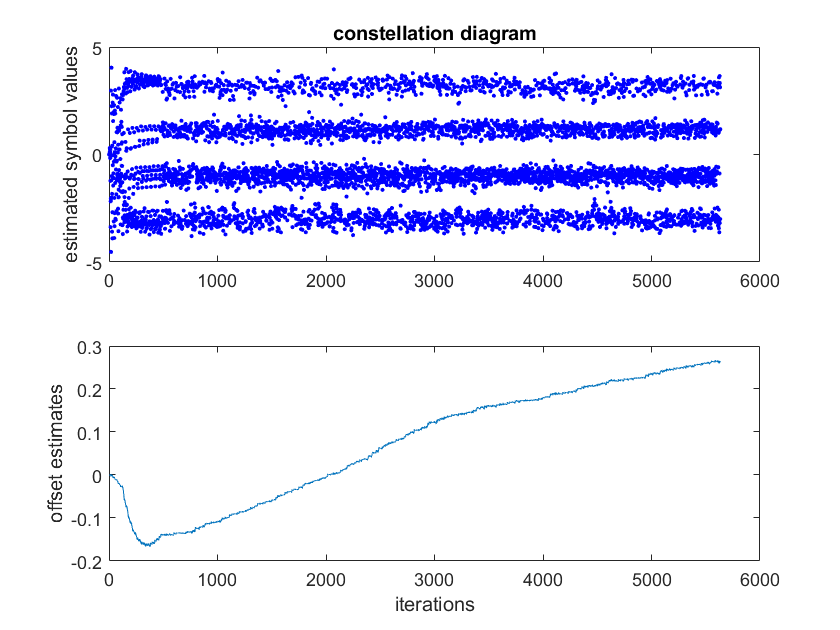


subplot(2,1,1), plot(y(1:i-2),'b.')       % plot constellation diagram
title('constellation diagram');
ylabel('estimated symbol values')
subplot(2,1,2), plot(tausave2(1:i-2))       % plot trajectory of tau
ylabel('offset estimates'), xlabel('iterations')

## Correlation

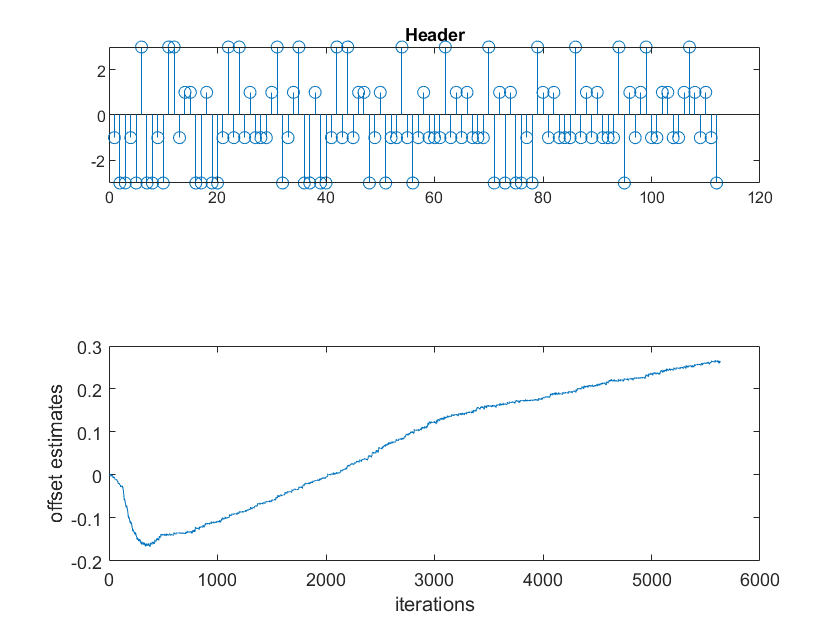

head = letters2pam('A0Oh well whatever Nevermind');
c=xcorr(head, y);                 % do cross correlation
[m,ind]=max(abs(c));                        % location of largest correlation

headstart=length(y)-ind+1;          % place where header starts
headstart = mod(headstart, (112+400));



figure(11),
subplot(3,1,1), stem(head)             % plot header
title('Header')

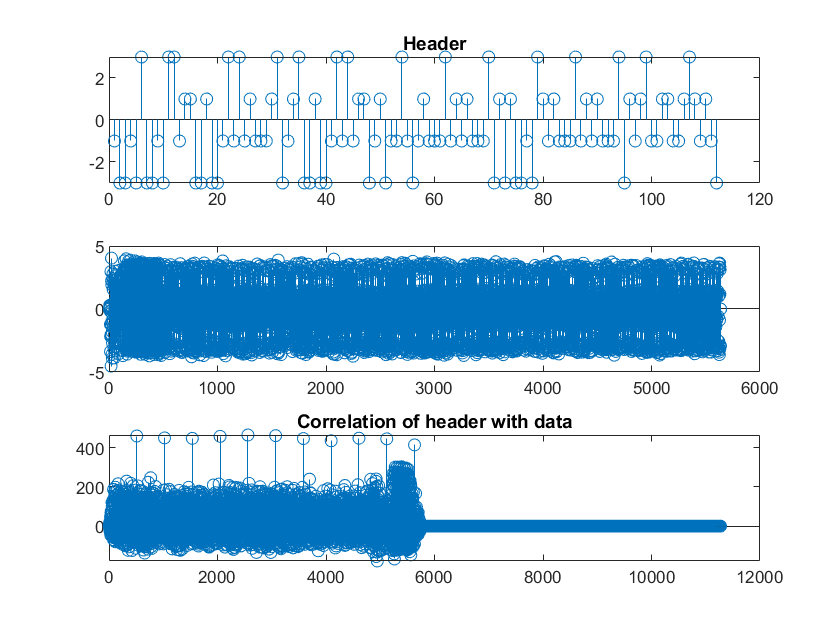

subplot(3,1,2), stem(y)             % plot data sequencetitle('Data with embedded header')
subplot(3,1,3), stem(c)                % plot correlation
title('Correlation of header with data')

z =y(headstart+112:end);




## Decoding


% decision device and symbol matching performance assessment
mprime=quantalph(z,[-3,-1,1,3])';         
cvar=(mprime-z)*(mprime-z)'/length(mprime)  % cluster variance

cvar = 0.0795


% decode decision device output to text string
reconstructed_message=pam2letters(mprime);   % reconstruct message
reconstructed_message = strrep(reconstructed_message,'A0Oh well whatever Nevermind','')

reconstructed_message =     'pq2345678901230567890123456789012345678901234567890123456789012345678901234567890123456789
     An den Mond
     Johann Wolfgang von Goethe, 1749-1832
     
     Fuellest wieder Busch und Tal
     Still mit Nebelglanz,
     Loesest endlich auch einmal
     Meine Seele ganz;
     
     Breitest ueber mein Gefid
     Lindernd deinen Blick,
     Wie des Freundes Auge mild
     Ueber mein Ceschick.
     
     Jeden Nachklang fuehlt mein Herz
     Froh und trueber Zeit
     Wandle zwischen Freud und Schmerz
     In der Einsamkeit.
     
     Fliesse, fliesse, lieber Fluss!
     Nimmer werd ich froh,
     So verrauschte Scherz und Kuss,
     Und die Treue so.
     
     Ich besass es doch einmal,
     Was so koestlich ist!
     Dass man doch zu seiner Qual
     Nimmer es vergisst!
     
     Rausche, Fluss, das Tal entlang,
     Ohne Rast und Ruh,
     Rausche, fluestre meinem Sang
     Melodien zu.
     
     Wenn du in der Winternacht
     Wuetend ueberschwills